# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');

simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step
simul.antiWindUp = 1;   % takes values in {-1, 1} -1 anti-windup loop deactivated 1 activated

warning('off','all')

### **[2.1] ANTI-WINDUP**

simul.FFW = 0;          % deactivating Feed-Forward
simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stepdeg = 360;

%PID values that make with and without Anti-WindUp simulations respect
%required settling time specifications
pid.K = 20;
pid.Kd = 0.15;
pid.Ki = 2;

Simulation with suggested Anti-WindUp constant

awu.a = 5;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

anti_windup_step_suggested = sim('lab1_PID','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
save('anti_windup_step_suggested.mat','anti_windup_step_suggested');

Simulation with adequate Anti-WindUp Constant

awu.a = 0.1;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

anti_windup_step = sim('lab1_PID','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
stepinfo(anti_windup_step.thl_meas.signals.values,anti_windup_step.thref.time,simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1086
    TransientTime: 1.1491
     SettlingTime: 1.1491
      SettlingMin: 324.5400
      SettlingMax: 354.0600
        Overshoot: 0
       Undershoot: 0
             Peak: 354.0600
         PeakTime: 1.1670


save('anti_windup_step.mat','anti_windup_step');

Simulation without Anti-WindUp

awu.Kw = 0;        % Disable Anti windup

no_anti_windup_step = sim('lab1_PID','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
stepinfo(no_anti_windup_step.thl_meas.signals.values,no_anti_windup_step.thref.time,simul.stepdeg, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
         RiseTime: 0.1080
    TransientTime: 1.1461
     SettlingTime: 1.1461
      SettlingMin: 326.3400
      SettlingMax: 371.5200
        Overshoot: 3.2000
       Undershoot: 0
             Peak: 371.5200
         PeakTime: 1.1720


save('no_anti_windup_step.mat','no_anti_windup_step');

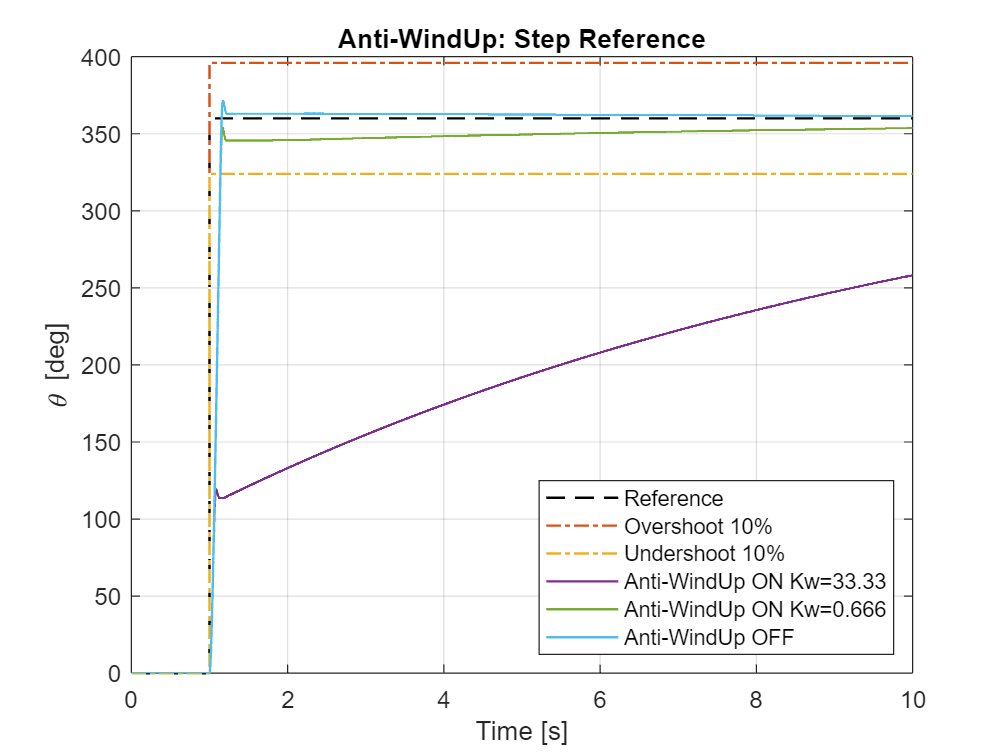

%Plotting compared results
figure

plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values,'--', 'LineWidth',1,'Color','black');
hold on;
plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values*1.10,'-.', 'LineWidth',1);
plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values*0.9,'-.', 'LineWidth',1);
plot(anti_windup_step_suggested.thl_meas.time, anti_windup_step_suggested.thl_meas.signals.values, 'LineWidth',1);
plot(anti_windup_step.thl_meas.time, anti_windup_step.thl_meas.signals.values, 'LineWidth',1);
plot(no_anti_windup_step.thl_meas.time, no_anti_windup_step.thl_meas.signals.values, 'LineWidth',1);
grid on;
legend('Reference','Overshoot 10%', 'Undershoot 10%','Anti-WindUp ON Kw=33.33','Anti-WindUp ON Kw=0.666', 'Anti-WindUp OFF','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-WindUp: Step Reference');

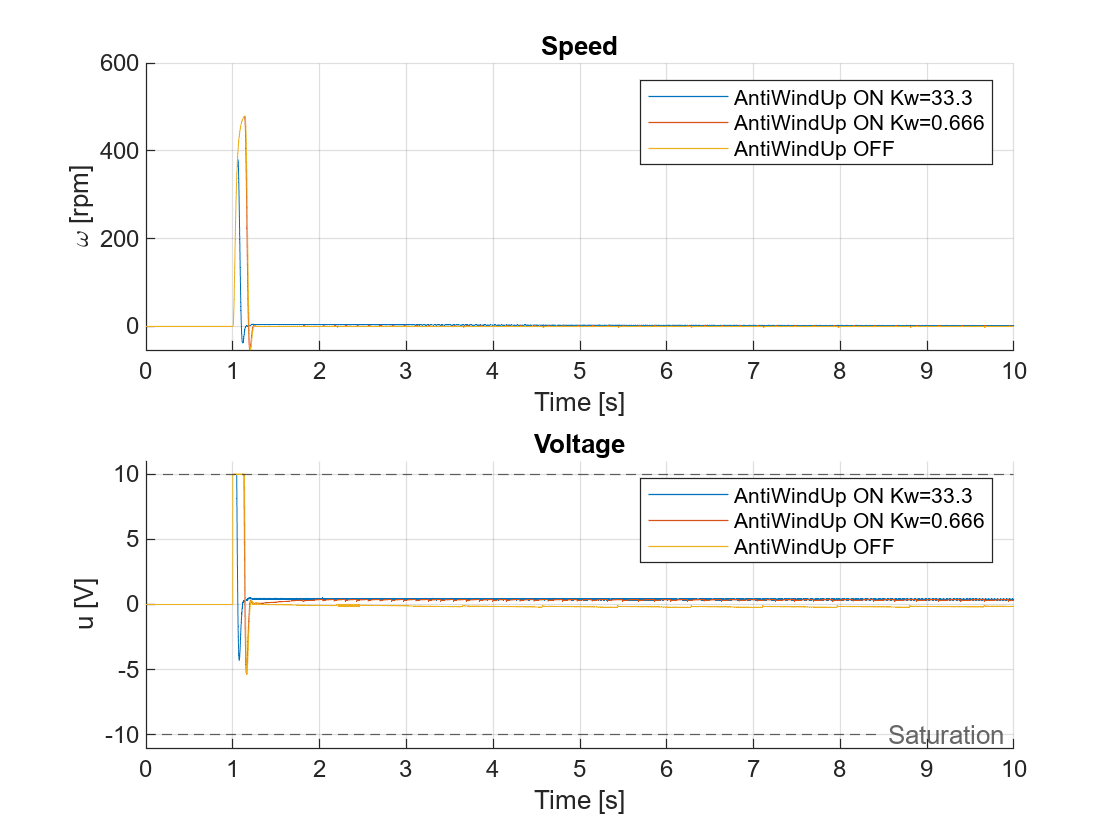

figure
subplot(2,1,1);
%plot(no_anti_windup_step.wref.time, no_anti_windup_step.wref.signals.values,'--');
hold on;
plot(anti_windup_step_suggested.wl_meas.time, anti_windup_step_suggested.wl_meas.signals.values);
plot(anti_windup_step.wl_meas.time, anti_windup_step.wl_meas.signals.values);
plot(no_anti_windup_step.wl_meas.time, no_anti_windup_step.wl_meas.signals.values);
legend('AntiWindUp ON Kw=33.3', 'AntiWindUp ON Kw=0.666', 'AntiWindUp OFF')
grid on;
xlabel('Time [s]')
ylabel('\omega [rpm]')
title('Speed')
subplot(2,1,2);
hold on;
plot(anti_windup_step_suggested.u.time, anti_windup_step_suggested.u.signals.values);
plot(anti_windup_step.u.time, anti_windup_step.u.signals.values);
plot(no_anti_windup_step.u.time, no_anti_windup_step.u.signals.values);
legend('AntiWindUp ON Kw=33.3', 'AntiWindUp ON Kw=0.666', 'AntiWindUp OFF')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','HandleVisibility','off');
yline(-10,'--','Saturation','LabelVerticalAlignment', 'middle','HandleVisibility','off');
ylim([-11 11])
title('Voltage')

### [2.2] FEED-FORWARD

simul.select1 = 3;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.FFW = 1;          % enables FFW, set 0 to disable
awu.Kw = 0;             % Disable Anti windup

Calculating PID gains required

a = 320;                      
pid.K = dK * cos(dPh);

Td = (tan(dPh)+sqrt(tan(dPh)^2+4/a))/(2*perf.wg);
Ti = a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid);

    Ki: 3.2823
    Kd: 0.0858
     K: 9.4929



Simulating **with** Feedforward

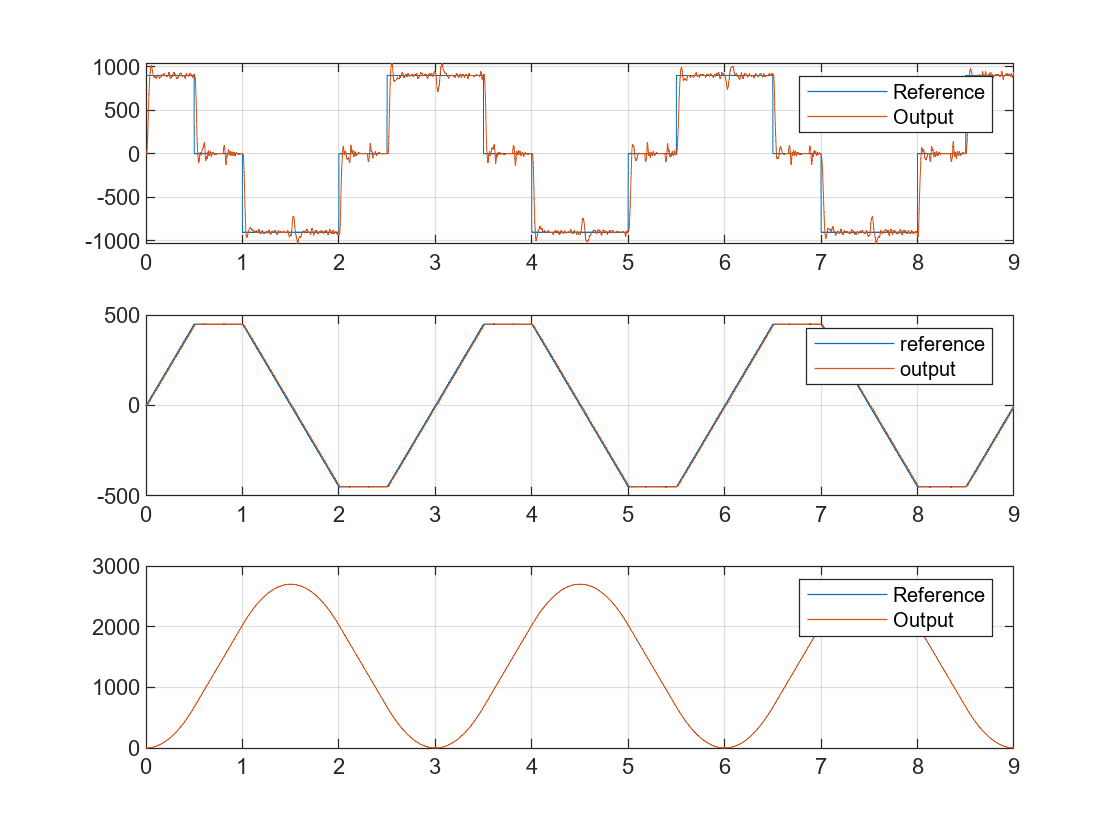

feedforward_sim = sim('lab1_PID','StartTime','0','StopTime','9', 'AlgebraicLoopMsg', 'off');
save('feedforward_sim.mat','feedforward_sim');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(feedforward_sim.aref.time, feedforward_sim.aref.signals.values);
hold on;
plot(feedforward_sim.al_meas.time, feedforward_sim.al_meas.signals.values);
legend('Reference', 'Output')
grid on;
subplot(3,1,2);
plot(feedforward_sim.wref.time, feedforward_sim.wref.signals.values);
hold on;
plot(feedforward_sim.wl_meas.time, feedforward_sim.wl_meas.signals.values);
legend('reference', 'output')
grid on;
subplot(3,1,3);
plot(feedforward_sim.thref.time, feedforward_sim.thref.signals.values);
hold on;
plot(feedforward_sim.thl_meas.time, feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;

Simulating **without** Feedforward

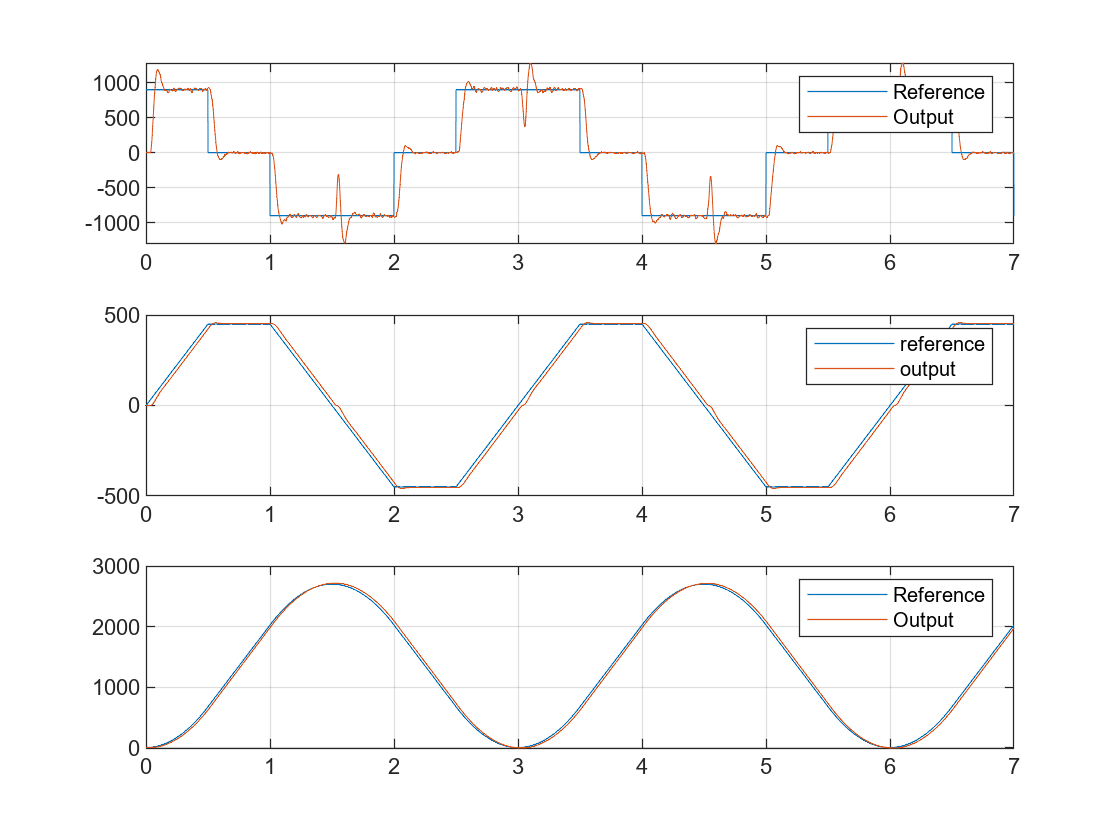

simul.FFW = 0;          % enables FFW, set 0 to disable

no_feedforward_sim = sim('lab1_PID','StartTime','0','StopTime','9', 'AlgebraicLoopMsg', 'off');
save('no_feedforward_sim.mat','no_feedforward_sim');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(no_feedforward_sim.aref.time, no_feedforward_sim.aref.signals.values);
hold on;
plot(no_feedforward_sim.al_meas.time, no_feedforward_sim.al_meas.signals.values);
legend('Reference', 'Output')
grid on;
xlim([0 7])
subplot(3,1,2);
plot(no_feedforward_sim.wref.time, no_feedforward_sim.wref.signals.values);
hold on;
plot(no_feedforward_sim.wl_meas.time, no_feedforward_sim.wl_meas.signals.values);
legend('reference', 'output')
grid on;
xlim([0 7])
subplot(3,1,3);
plot(no_feedforward_sim.thref.time, no_feedforward_sim.thref.signals.values);
hold on;
plot(no_feedforward_sim.thl_meas.time, no_feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;
xlim([0 7])

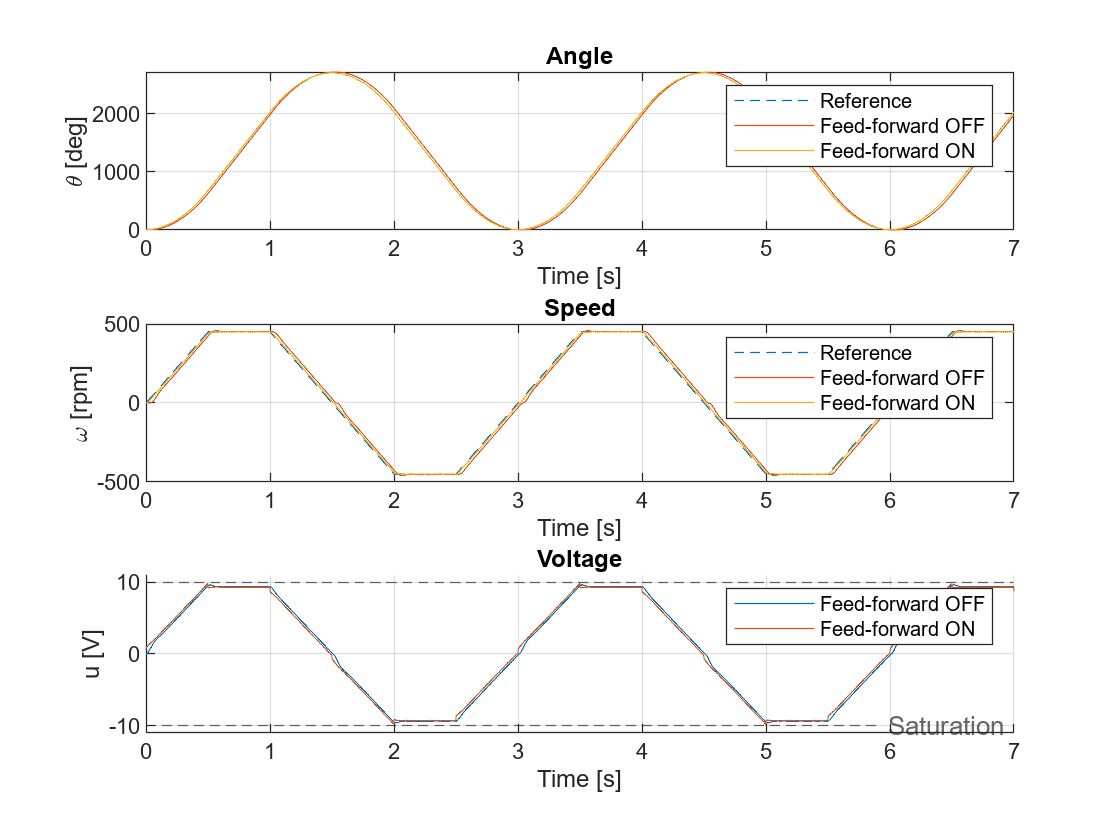

figure
title('Feedforward Results Comparison')
subplot(3,1,1);
plot(no_feedforward_sim.thref.time, no_feedforward_sim.thref.signals.values,'--');
hold on;
plot(no_feedforward_sim.thl_meas.time, no_feedforward_sim.thl_meas.signals.values);
plot(feedforward_sim.thl_meas.time, feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
title('Angle')
xlabel('Time [s]')
ylabel('\theta [deg]')
grid on;
xlim([0 7])
subplot(3,1,2);
plot(no_feedforward_sim.wref.time, no_feedforward_sim.wref.signals.values,'--');
hold on;
plot(no_feedforward_sim.wl_meas.time, no_feedforward_sim.wl_meas.signals.values);
plot(feedforward_sim.wl_meas.time, feedforward_sim.wl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
title('Speed')
xlabel('Time [s]')
ylabel('\omega [rpm]')
grid on;
xlim([0 7])
subplot(3,1,3);
hold on;
plot(no_feedforward_sim.u.time, no_feedforward_sim.u.signals.values);
plot(feedforward_sim.u.time, feedforward_sim.u.signals.values);
legend('Feed-forward OFF','Feed-forward ON')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','HandleVisibility','off');
yline(-10,'--','Saturation','LabelVerticalAlignment', 'middle','HandleVisibility','off');
ylim([-11 11])
xlim([0 7])
title('Voltage')

## STATE SPACE

### **[3.2] Nominal Traking design **

Consider the problem of asymptotically tracking a step reference input $r\left(t\right)=r_{\infty } \delta_{-1} \left(t\right)$ in the ideal situation of perfect knowledge of the plant dynamics and lack of any external disturbance (nominal tracking problem). The perfect steady state tracking condition ${y_{\infty } =r_{\infty } }$ imposes that $x_{\infty }$ and $u_{\infty }$ satisfy the conditions


$$\left\lbrack \begin{array}{cc}
A & B\\
C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
N_x \\
N_u 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


where $u=-K\;x+\left(N_u +{K\;N}_x \right)r_{\infty }$ and $K$is a state feedback gain that asymptotically stabilises the closed–loop system.

For the simulations, consider either an “ideal” situation with no static friction, or a “real” situation with a static friction torque as estimated in the previous laboratory activity. Perform the tests with three different position set–points, e.g. **40°**, **70°** and **120°**.

simul.stepdeg = 40;
nominal_track_40 = sim('lab1_ss','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
save('nominal_track_40.mat','nominal_track_40');

simul.stepdeg = 70;
nominal_track_70 = sim('lab1_ss','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
save('nominal_track_70.mat','nominal_track_70');

simul.stepdeg = 120;
nominal_track_120 = sim('lab1_ss','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
save('nominal_track_120.mat','nominal_track_120');

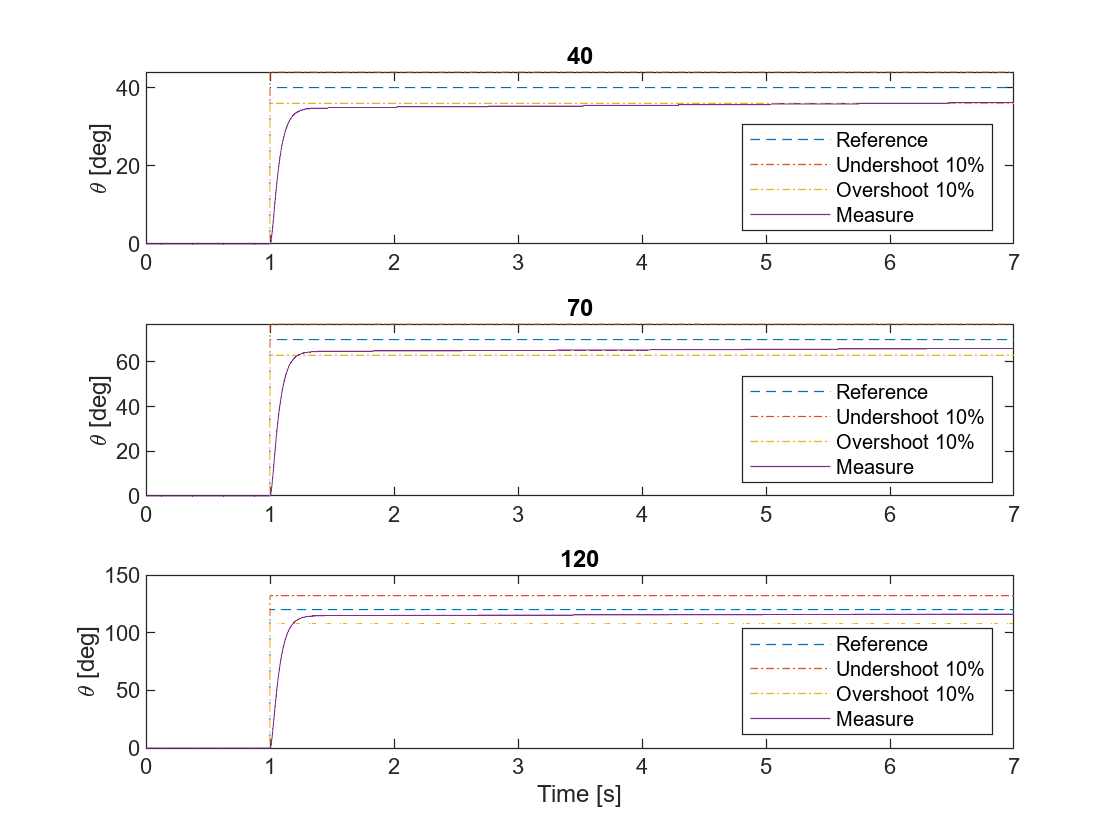

figure
subplot(3,1,1)
plot(nominal_track_40.thref.time, nominal_track_40.thref.signals.values,'--');
hold on;
plot(nominal_track_40.thref.time, nominal_track_40.thref.signals.values*1.10,'-.');
plot(nominal_track_40.thref.time, nominal_track_40.thref.signals.values*0.9,'-.');
plot(nominal_track_40.thl_meas.time, nominal_track_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
title('40')
xlim([0 7])
ylabel('\theta [deg]')

subplot(3,1,2)
plot(nominal_track_70.thref.time, nominal_track_70.thref.signals.values,'--');
hold on;
plot(nominal_track_70.thref.time, nominal_track_70.thref.signals.values*1.10,'-.');
plot(nominal_track_70.thref.time, nominal_track_70.thref.signals.values*0.9,'-.');
plot(nominal_track_70.thl_meas.time, nominal_track_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
title('70')
xlim([0 7])
ylabel('\theta [deg]')

subplot(3,1,3)
plot(nominal_track_120.thref.time, nominal_track_120.thref.signals.values,'--');
hold on;
plot(nominal_track_120.thref.time, nominal_track_120.thref.signals.values*1.10,'-.');
plot(nominal_track_120.thref.time, nominal_track_120.thref.signals.values*0.9,'-.');
plot(nominal_track_120.thl_meas.time, nominal_track_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
title('120')
xlim([0 7])
xlabel('Time [s]')
ylabel('\theta [deg]')

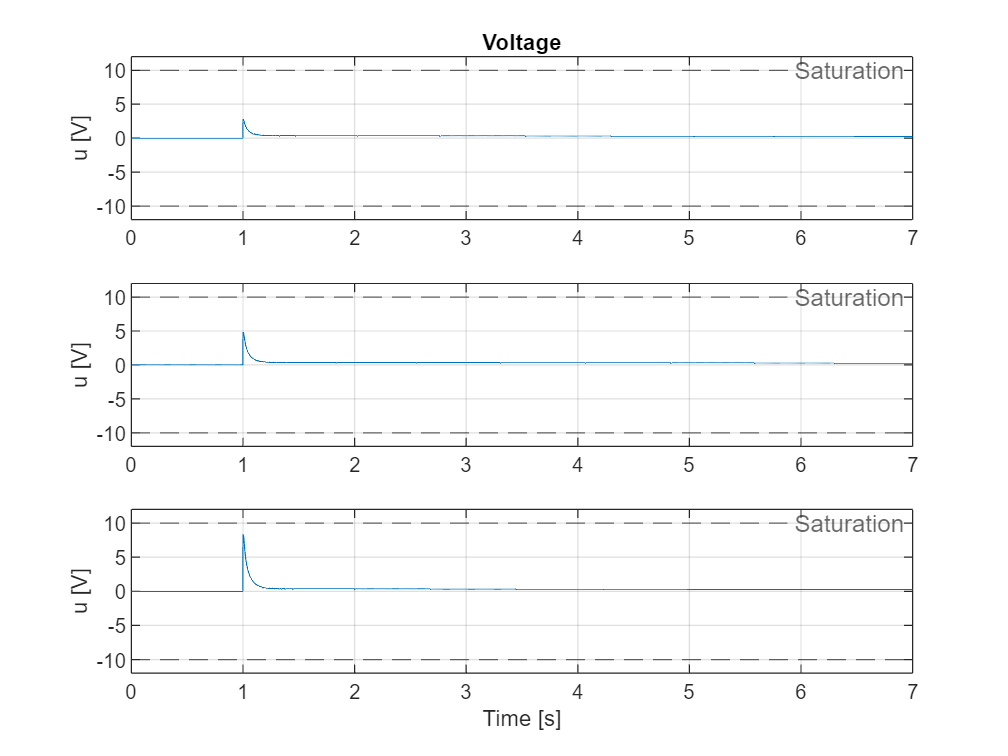

figure
subplot(3,1,1)
plot(nominal_track_40.u.time, nominal_track_40.u.signals.values);
hold on;
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
xlim([0 7])
title('Voltage')
grid on
subplot(3,1,2)
plot(nominal_track_70.u.time, nominal_track_70.u.signals.values);
hold on;
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
xlim([0 7])
grid on
subplot(3,1,3)
plot(nominal_track_120.u.time, nominal_track_120.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
xlim([0 7])
grid on
subplot(3,1,2)

### **[3.2] Robust Traking **

**of constant postion set-point and rejection of constant load disturbances**

In this case we consider the augmented state system


$$\left\lbrack \begin{array}{c}
\dot{x_I } \left(t\right)\\
\dot{x} \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & C\\
0 & A
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_I \left(t\right)\\
x\left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
B
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$


If the pair (A, B) is reachable and the open loop transfer function H(s) = C(sI − A)−1B has no zeros at s = 0, then Σe is reachable and therefore the eigenvalues of the closed–loop system, namely the eigenvalues of


$$A_{\textrm{cl}} =\left\lbrack \begin{array}{cc}
0 & C\\
-B\;K_I  & A-B\;K
\end{array}\right\rbrack$$


can be placed at arbitrary position by properly selecting the feedback gain matrix Ke.

simul.stepdeg = 40;
robust_track_40 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
save('robust_track_40.mat','robust_track_40');

simul.stepdeg = 70;
robust_track_70 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
save('robust_track_70.mat_robust','robust_track_70');

simul.stepdeg = 120;
robust_track_120 = sim('lab1_ss_robust','StartTime','0','StopTime','10', 'AlgebraicLoopMsg', 'off');
save('robust_track_120.mat','robust_track_120');

PLOTS FOR ROBUST CONTROL

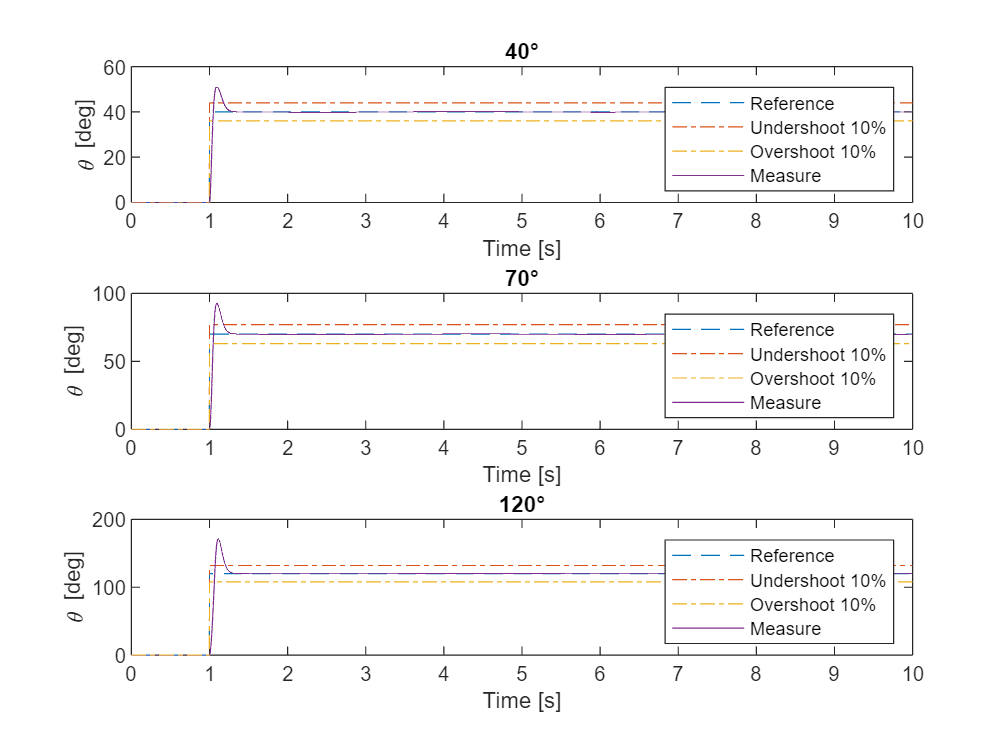

figure
subplot(3,1,1)
plot(robust_track_40.thref.time, robust_track_40.thref.signals.values,'--');
hold on;
plot(robust_track_40.thref.time, robust_track_40.thref.signals.values*1.10,'-.');
plot(robust_track_40.thref.time, robust_track_40.thref.signals.values*0.9,'-.');
plot(robust_track_40.thl_meas.time, robust_track_40.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('40°')

subplot(3,1,2)
plot(robust_track_70.thref.time, robust_track_70.thref.signals.values,'--');
hold on;
plot(robust_track_70.thref.time, robust_track_70.thref.signals.values*1.10,'-.');
plot(robust_track_70.thref.time, robust_track_70.thref.signals.values*0.9,'-.');
plot(robust_track_70.thl_meas.time, robust_track_70.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('70°')

subplot(3,1,3)
plot(robust_track_120.thref.time, robust_track_120.thref.signals.values,'--');
hold on;
plot(robust_track_120.thref.time, robust_track_120.thref.signals.values*1.10,'-.');
plot(robust_track_120.thref.time, robust_track_120.thref.signals.values*0.9,'-.');
plot(robust_track_120.thl_meas.time, robust_track_120.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('120°')

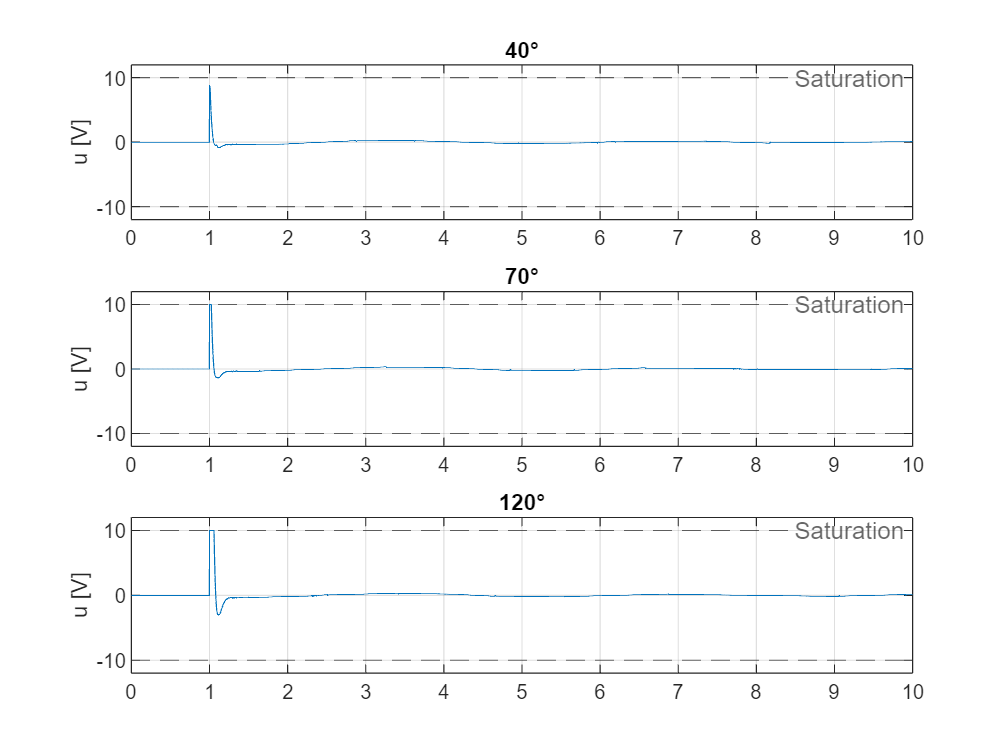

figure("Name",'Voltage')
subplot(3,1,1)
plot(robust_track_40.u.time, robust_track_40.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('40°')
grid on
subplot(3,1,2)
plot(robust_track_70.u.time, robust_track_70.u.signals.values);
hold on;
%xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
title('70°')
grid on
subplot(3,1,3)
plot(robust_track_120.u.time, robust_track_120.u.signals.values);
hold on;
title('120°')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-12 12])
grid on

### **[3.3] Error space**

Design a position state–space controller for the Quanser SRV–02 servomotor that guarantees the perfect steady state robust tracking of a sinusoidal position reference of a specified pe- riod Tr, and perfect rejection of constant load disturbances, using the error–space approach.

#### POINT 6 OF ASSIGNMENT


%%% Reference frequencies
ssError.amp = 0;                    % Choose sinusoide amplitude
ssError.Trs = 0.5;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi/ssError.Trs;    % T[s] -> w[rad/s]

%%% Signal model
% By IMP: char. Equation: (s^2 + wr^2) * s
ssError.denomH = [1 0 ssError.wrs^2 0]; % denominator of compensator H(s)
ssError.Ar = [0 1 0; 0 0 1; 0 -ssError.wrs^2 0]; % maybe change to alternate for better condition number

%%% Error Space Model
ssError.Az = [ssError.Ar, [zeros(2,2);ssP.C]; zeros(2,3), ssP.A];
ssError.Bz = [zeros(3,1); ssP.B]; % Note: Reachable as ssP is reachable and has no zeros (see handout)

%%% Place Poles (TENTIATIVE VALUES FROM ASSIGNMENT -- TUNE!)
perf.wnmin = perf.sigmamin/perf.d; % Natural frequency from minimal performance criteria

% Matlab doesn't recognize that the poles below are conjugate, explicitly
% set the values.
% ssError.poles = perf.wnmin*[exp(1i*(-1+1/4)*pi) exp(1i*(-1-1/4)*pi) exp(1i*(-1+1/6)*pi) exp(1i*(-1-1/6)*pi) -1]; 

ssError.poles = perf.wnmin*[-0.7071-0.7071i -0.7071+0.7071i -0.8660-0.5000i  -0.8660+0.5000i -1.0000];
ssError.Kz = place(ssError.Az, ssError.Bz, ssError.poles);
ssError.Kz % First gain on order of 10^5, something is wrong.

ans = 1.0e+05 *

    2.8192    0.2598    0.0173    0.0005    0.0000


%%% Translate back to real system
ssError.nomH = flip(ssError.Kz(1:3)); % nominator of compensator H(s), flip to get correct order for tf
ssError.K = ssError.Kz(4:5); % State-Feedback gain on original system


SIMULATIONS

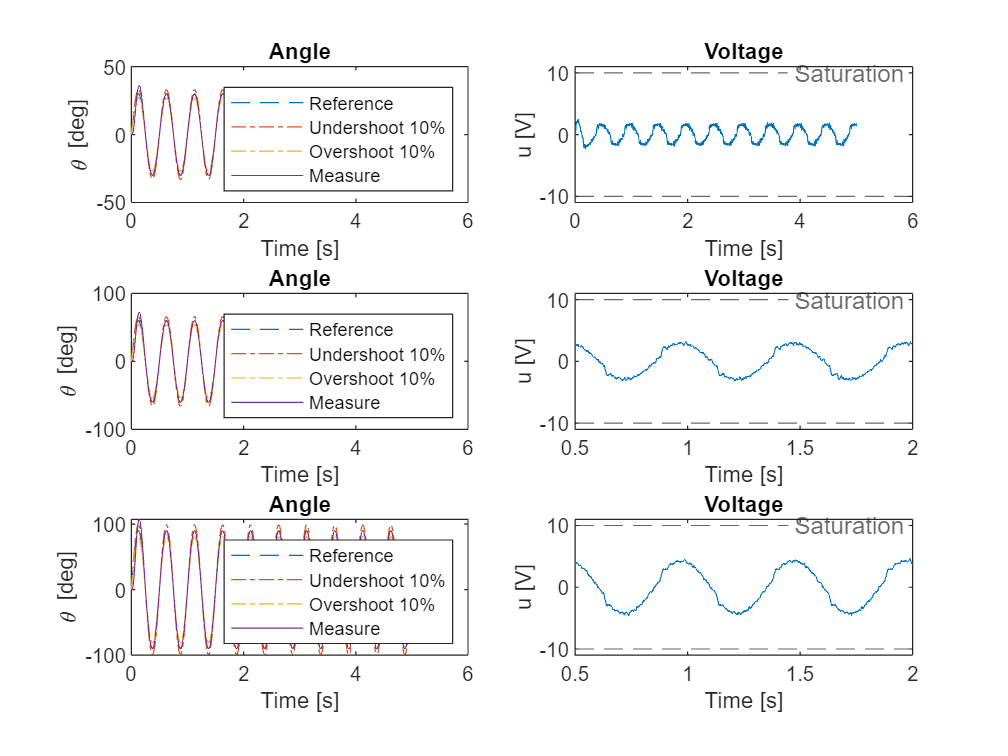

ssError.amp = 30;
error_space.point_6.amp30 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');
ssError.amp = 60;
error_space.point_6.amp60 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');
ssError.amp = 90;
error_space.point_6.amp90 =sim('lab1_error_space','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(3,2,1)
plot(error_space.point_6.amp30.thref.time, error_space.point_6.amp30.thref.signals.values,'--');
hold on;
plot(error_space.point_6.amp30.thref.time, error_space.point_6.amp30.thref.signals.values*1.10,'-.');
plot(error_space.point_6.amp30.thref.time, error_space.point_6.amp30.thref.signals.values*0.9,'-.');
plot(error_space.point_6.amp30.thl_meas.time, error_space.point_6.amp30.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,2)
plot(error_space.point_6.amp30.u.time, error_space.point_6.amp30.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')


subplot(3,2,3)
plot(error_space.point_6.amp60.thref.time, error_space.point_6.amp60.thref.signals.values,'--');
hold on;
plot(error_space.point_6.amp60.thref.time, error_space.point_6.amp60.thref.signals.values*1.10,'-.');
plot(error_space.point_6.amp60.thref.time, error_space.point_6.amp60.thref.signals.values*0.9,'-.');
plot(error_space.point_6.amp60.thl_meas.time, error_space.point_6.amp60.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,4)
plot(error_space.point_6.amp60.u.time, error_space.point_6.amp60.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')


subplot(3,2,5)
plot(error_space.point_6.amp90.thref.time, error_space.point_6.amp90.thref.signals.values,'--');
hold on;
plot(error_space.point_6.amp90.thref.time, error_space.point_6.amp90.thref.signals.values*1.10,'-.');
plot(error_space.point_6.amp90.thref.time, error_space.point_6.amp90.thref.signals.values*0.9,'-.');
plot(error_space.point_6.amp90.thl_meas.time, error_space.point_6.amp90.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(3,2,6)
plot(error_space.point_6.amp90.u.time, error_space.point_6.amp90.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')

#### POINT 7 OF THE ASSIGMENT

the behaviuor in the plot is normal since we are using a controller design for a specific sinusoid frequency at a different frequency

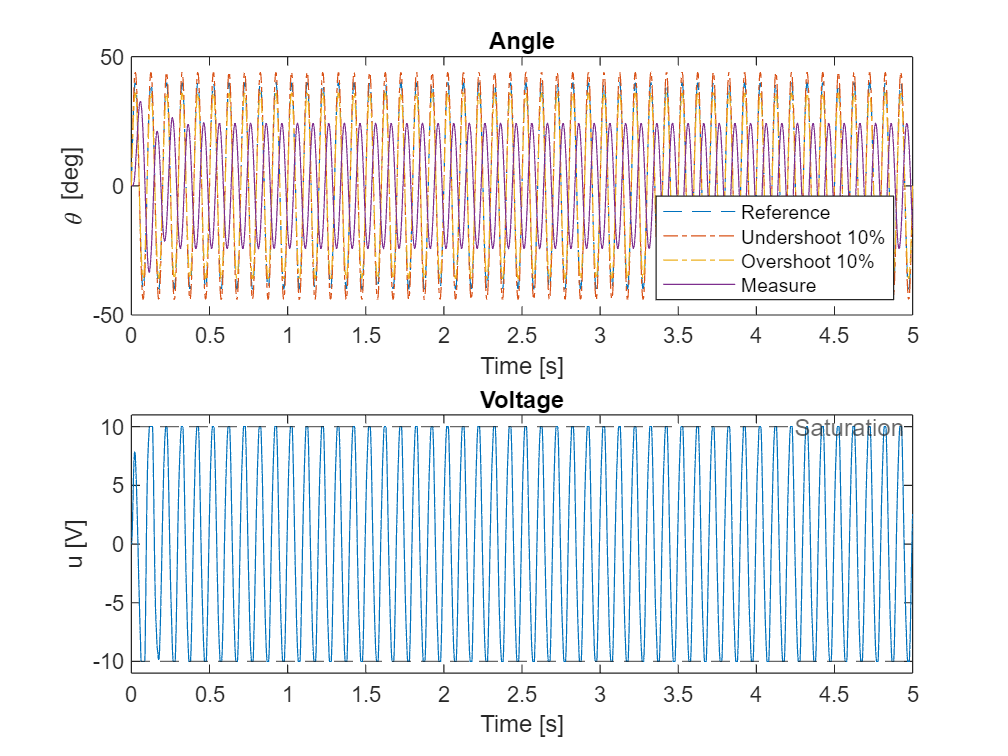


%%% Reference frequencies
ssError.amp = 40;                    % Choose sinusoide amplitude
ssError.Trs = 0.1;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi/ssError.Trs;    % T[s] -> w[rad/s]

error_space.point_7 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(2,1,1)
plot(error_space.point_7.thref.time, error_space.point_7.thref.signals.values,'--');
hold on;
plot(error_space.point_7.thref.time, error_space.point_7.thref.signals.values*1.10,'-.');
plot(error_space.point_7.thref.time, error_space.point_7.thref.signals.values*0.9,'-.');
plot(error_space.point_7.thl_meas.time, error_space.point_7.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(error_space.point_7.u.time, error_space.point_7.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

#### POINT 8 OF THE ASSIGMENT

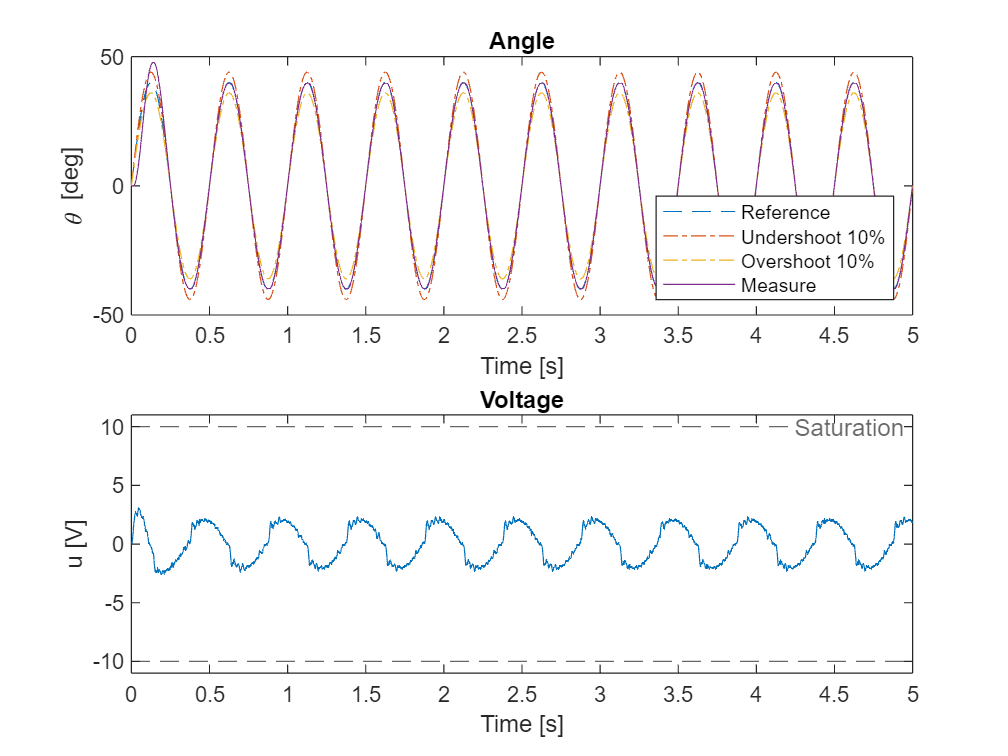


%%% Reference frequencies
ssError.amp = 40;                    % Choose sinusoide amplitude
ssError.Trs = 0.5;                 % Periods to track from assignment [s]
ssError.wrs = 2*pi/ssError.Trs;    % T[s] -> w[rad/s]

error_space.point_8 =sim('lab1_error_space','StartTime','0','StopTime','5', 'AlgebraicLoopMsg', 'off');

figure("Name",'Results')
subplot(2,1,1)
plot(error_space.point_8.thref.time, error_space.point_8.thref.signals.values,'--');
hold on;
plot(error_space.point_8.thref.time, error_space.point_8.thref.signals.values*1.10,'-.');
plot(error_space.point_8.thref.time, error_space.point_8.thref.signals.values*0.9,'-.');
plot(error_space.point_8.thl_meas.time, error_space.point_8.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
subplot(2,1,2)
plot(error_space.point_8.u.time, error_space.point_8.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
title('Voltage')

### [Bonus] Extended Estimator

ssError.amp = 2;
simul.stepdeg = 70;

ssError.ridx = 1;
lab1_estimator_1 = sim('lab1_extended_estimator','StartTime','0','StopTime','2', 'AlgebraicLoopMsg', 'off');
save('lab1_estimator_1.mat','lab1_estimator_1');


figure("Name",'Estimator with T = +')
subplot(2,1,1)
plot(lab1_estimator_1.thref.time, lab1_estimator_1.thref.signals.values,'--');
hold on;
plot(lab1_estimator_1.thref.time, lab1_estimator_1.thref.signals.values*1.10,'-.');
plot(lab1_estimator_1.thref.time, lab1_estimator_1.thref.signals.values*0.9,'-.');
plot(lab1_estimator_1.thl_meas.time, lab1_estimator_1.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
xlim([0 2])
subplot(2,1,2)
plot(lab1_estimator_1.u.time, lab1_estimator_1.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0 2])
title('Voltage')

### **CHALLENGE**

We want to reach the smallest rise time possible, compatible with an overshoot of 10%. We consider as input a step of 10V amplitude in order to reach the fastest possible response.

simul.stepdeg = 70;

awu.a = 2;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

simul.FFW = 1;          % enables FFW, set 0 to disable
pid.K=38;
pid.Ki=5; 
end_step=1.043;

lab1_challenge = sim('lab1_challenge','StartTime','0','StopTime','2', 'AlgebraicLoopMsg', 'off');
save('lab1_challenge.mat','lab1_challenge');

stepinfo(lab1_challenge.thl_meas.signals.values,lab1_challenge.thref.time,simul.stepdeg)
figure("Name",'Results')
subplot(2,1,1)
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values,'--');
hold on;
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values*1.10,'-.');
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values*0.9,'-.');
plot(lab1_challenge.thref.time, lab1_challenge.thref.signals.values*0.1,'-.');
plot(lab1_challenge.thl_meas.time, lab1_challenge.thl_meas.signals.values);
hold on;
legend('Reference','Undershoot 10%','Overshoot 10%','10% rise', 'Measure','Location','southeast');
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Angle')
xlim([0.5 2])
subplot(2,1,2)
plot(lab1_challenge.u.time, lab1_challenge.u.signals.values);
hold on;
xlabel('Time [s]')
ylabel('u [V]')
yline(10,'--','Saturation','LabelVerticalAlignment', 'middle');
yline(-10,'--');
ylim([-11 11])
xlim([0.5 2])
title('Voltage')